clearvars
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2')
cd('C:\Users\fogaren\Desktop\Leah_2018\0252116\1.1\data\0-data\ar30-03_final\ar30-03_final')


cast01 = readSBScnv( 'at30_001_hyst.cnv' );
cast02 = readSBScnv( 'at30_002_hyst.cnv' );
cast03 = readSBScnv( 'at30_003_hyst.cnv' ); % Default hysteresis
cast04 = readSBScnv( 'at30_004_hyst.cnv' );
cast05 = readSBScnv( 'at30_005_hyst.cnv' );
cast06 = readSBScnv( 'at30_006_hyst.cnv' );
cast07 = readSBScnv( 'at30_007_hyst.cnv' );
cast08 = readSBScnv( 'at30_008_hyst.cnv' );
cast09 = readSBScnv( 'at30_009_hyst.cnv' );
cast10 = readSBScnv( 'at30_010_hyst.cnv' );
cast11 = readSBScnv( 'at30_011_hyst.cnv' );
cast12 = readSBScnv( 'at30_012_hyst.cnv' );
cast13 = readSBScnv( 'at30_013_hyst.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2')

btl = readtable('Irminger_Sea-02_AT30-01_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum03 = btl(btl.Cast == 3,:);
btlsum04 = btl(btl.Cast == 4,:);
btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);
btlsum13 = btl(btl.Cast == 13,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year2')
btl03 = readtable('at30_003_hyst.csv','TextType','string');

btl04 = readtable('at30_004_hyst.csv','TextType','string');

btl05 = readtable('at30_005_hyst.csv','TextType','string');

btl06 = readtable('at30_006_hyst.csv','TextType','string');

btl09 = readtable('at30_009_hyst.csv','TextType','string');

btl10 = readtable('at30_010_hyst.csv','TextType','string');

btl11 = readtable('at30_011_hyst.csv','TextType','string');

btl12 = readtable('at30_012_hyst.csv','TextType','string');

btl13 = readtable('at30_013_hyst.csv','TextType','string');


% Join tables 
btlsum03 = join(btl03,btlsum03,'Keys',"Bottle");
btlsum04 = join(btl04,btlsum04,'Keys',"Bottle");
btlsum05 = join(btl05,btlsum05,'Keys',"Bottle");
btlsum06 = join(btl06,btlsum06,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");
btlsum11 = join(btl11,btlsum11,'Keys',"Bottle");
btlsum12 = join(btl12,btlsum12,'Keys',"Bottle");
btlsum13 = join(btl13,btlsum13,'Keys',"Bottle");

clear btl0* btl1* btl2*

btlsum_yr2 = [btlsum03; btlsum04; btlsum05; btlsum06; btlsum09; btlsum10; btlsum11;...
    btlsum12; btlsum13];
btlsum0 = btlsum_yr2; %

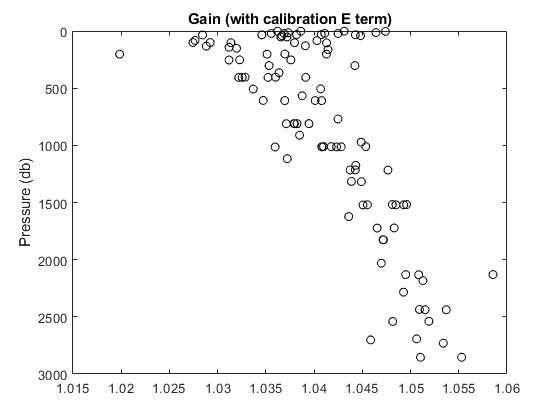

figure
plot(btlsum_yr2.Winkler_mLL./btlsum_yr2.Sbeox0ML_L,btlsum_yr2.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

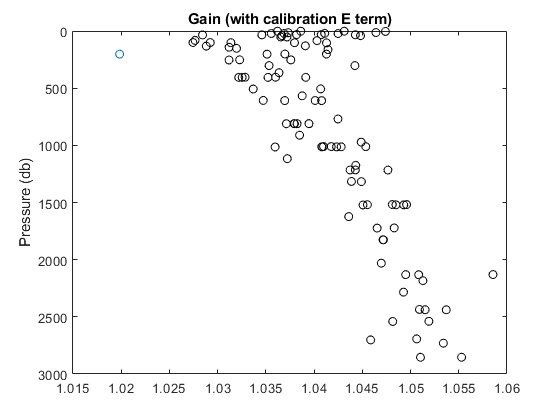

gain0_threshold = 1.025;
gain0 = btlsum0.Winkler_mLL./btlsum0.Sbeox0ML_L;
Wink_out = find(gain0 < gain0_threshold);
btlsum0.Winkler_mLL(Wink_out) = NaN;

figure
plot(btlsum_yr2.Winkler_mLL./btlsum_yr2.Sbeox0ML_L,btlsum_yr2.PrDM,'o')
hold on
plot(btlsum0.Winkler_mLL./btlsum0.Sbeox0ML_L,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 
cal.SOC = double(5.15150e-001);
cal.VOFFSET = double(-5.24000e-001);
cal.A = double(-4.56860e-003);
cal.B = double(2.57580e-004);
cal.C = double(-4.06010e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.11000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0712';
cal.OCALDATE = '05-Nov-14';

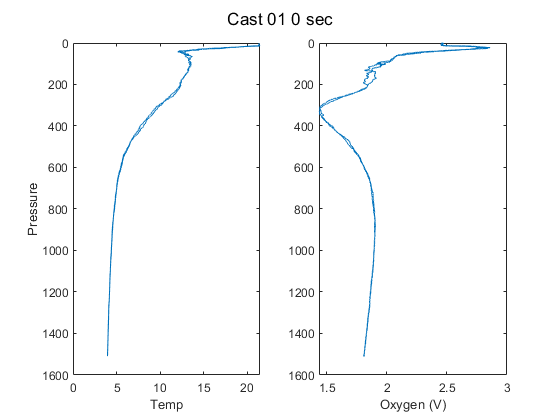

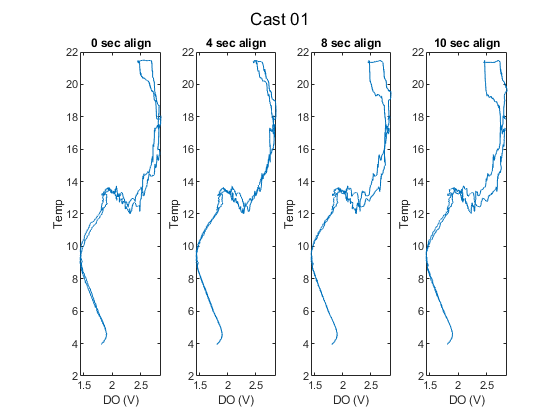

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 8; a3 = 10;

cast01 = align_CTD_KF(cast01,'Cast 01',a1,a2,a3);

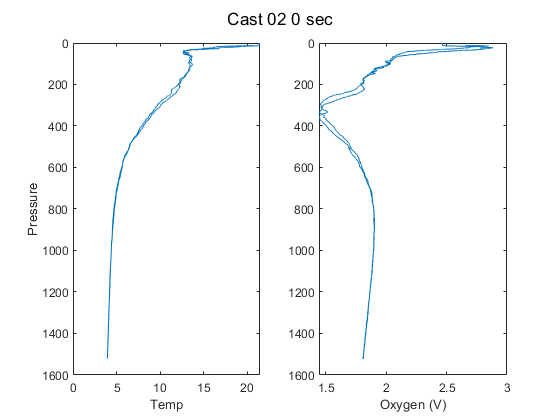

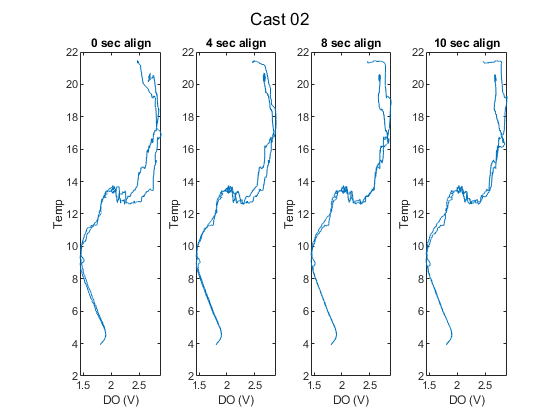

cast02 = align_CTD_KF(cast02,'Cast 02',a1,a2,a3);

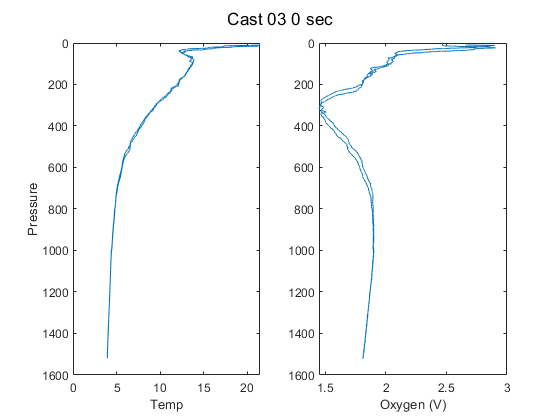

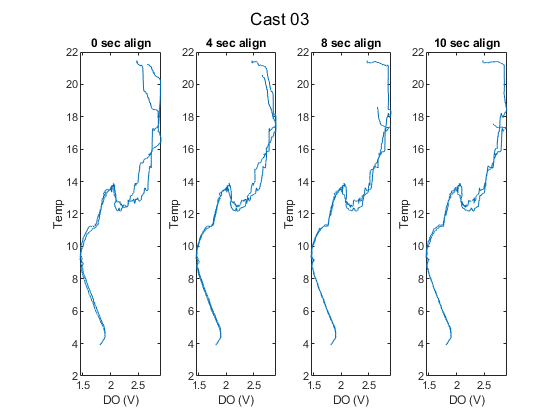

cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);

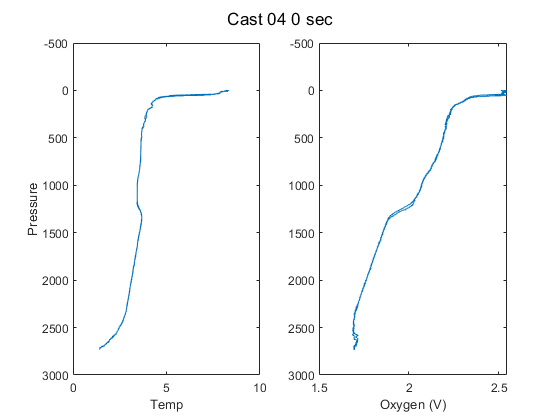

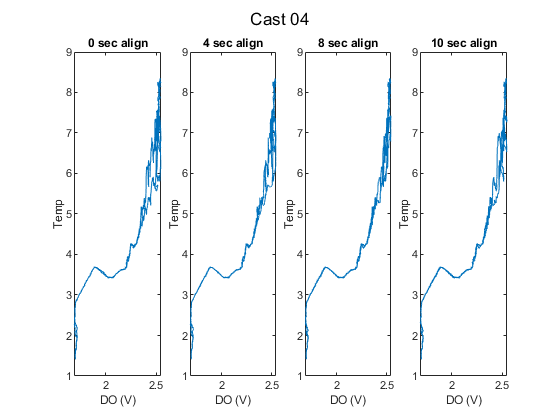

cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);

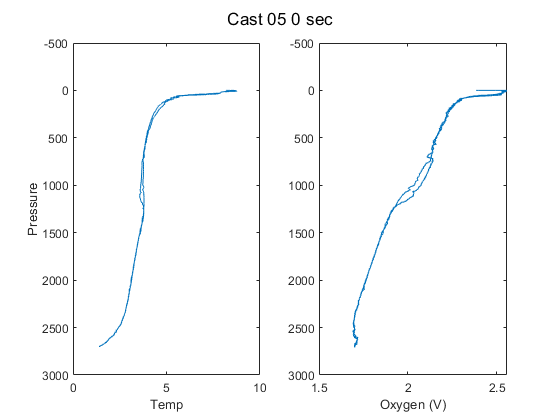

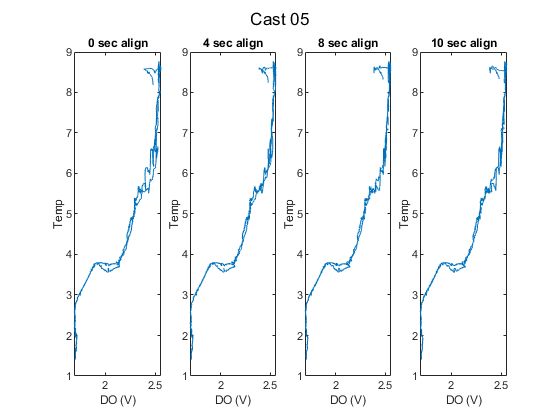

cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);

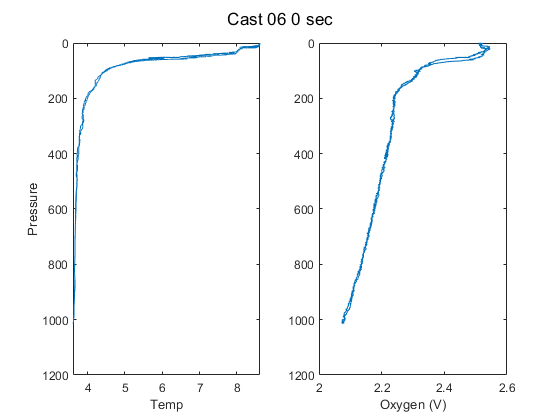

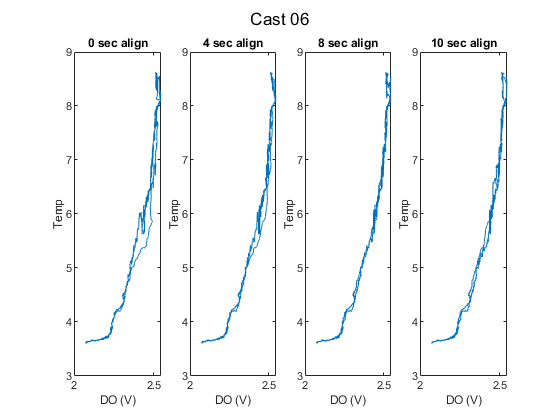

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

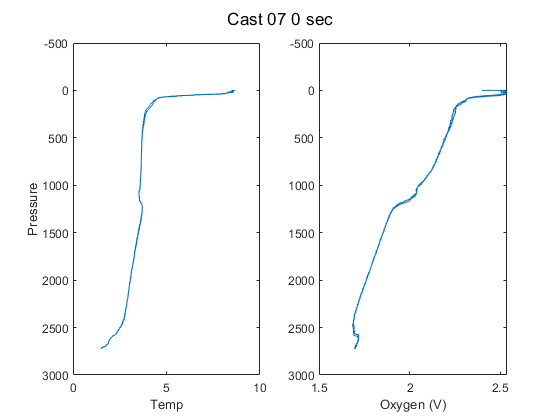

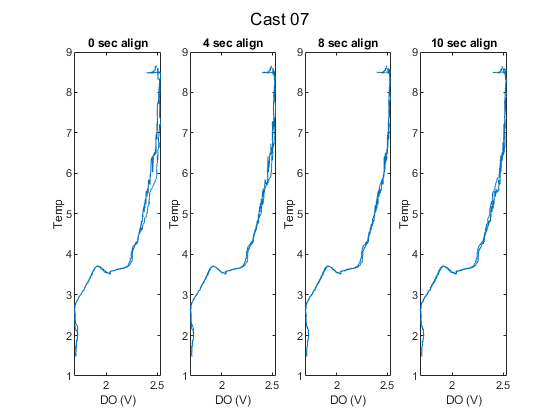

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

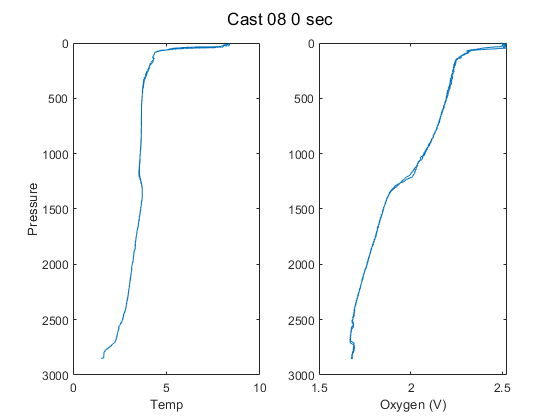

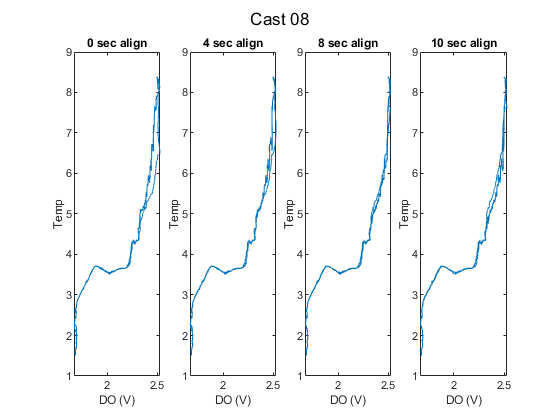

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

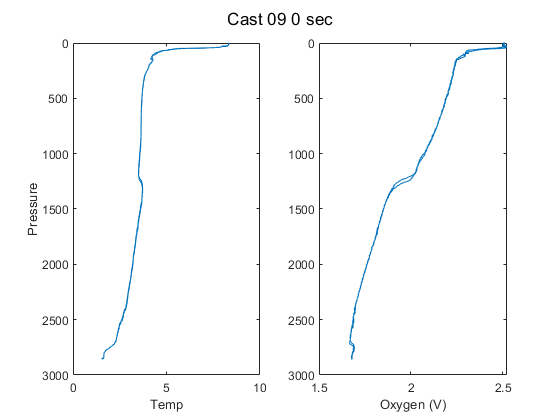

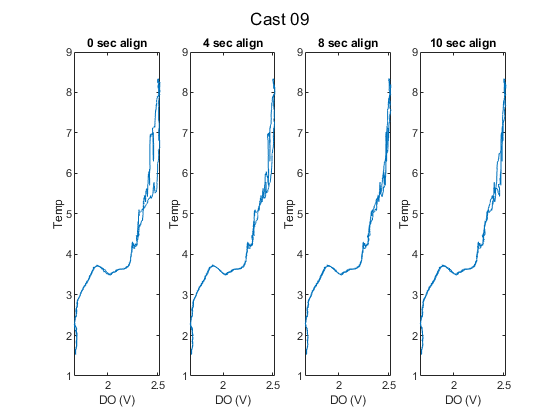

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

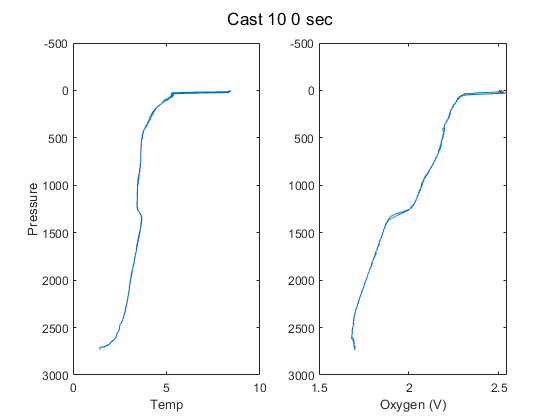

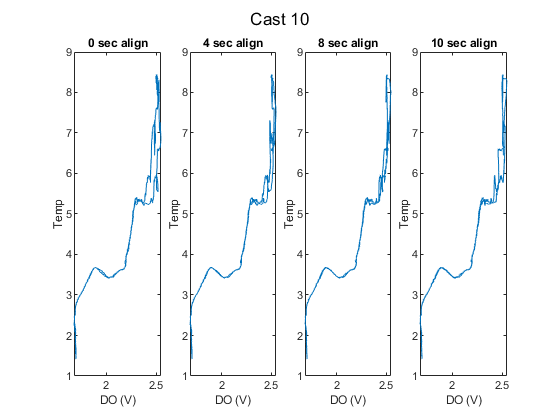

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);

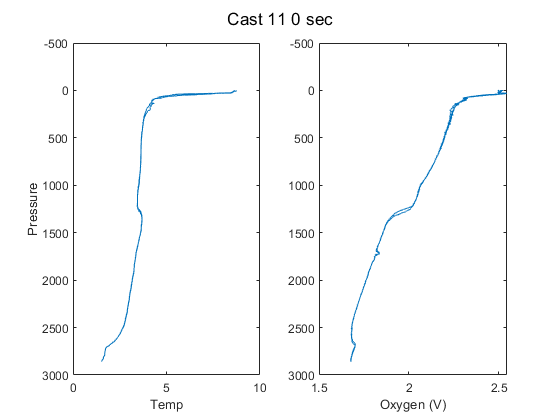

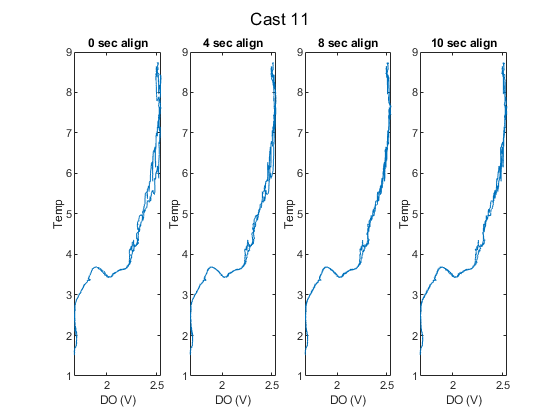

cast11 = align_CTD_KF(cast11,'Cast 11',a1,a2,a3);

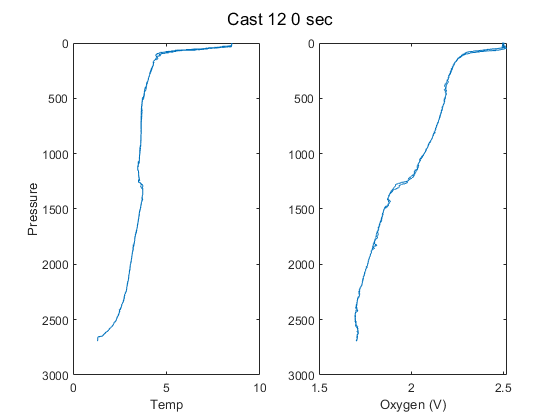

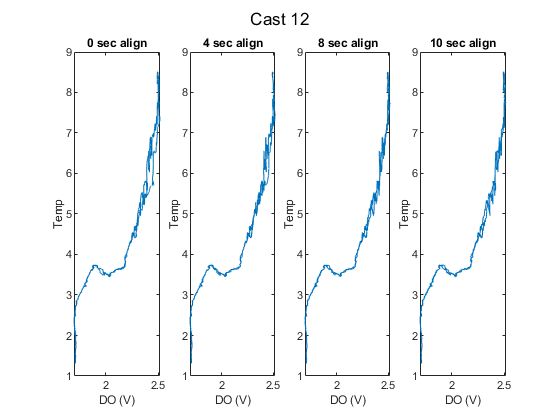

cast12 = align_CTD_KF(cast12,'Cast 12',a1,a2,a3);

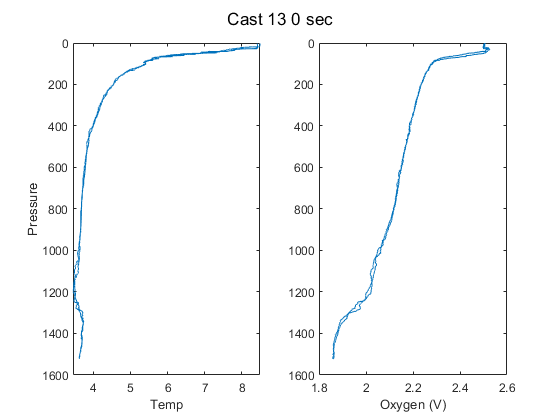

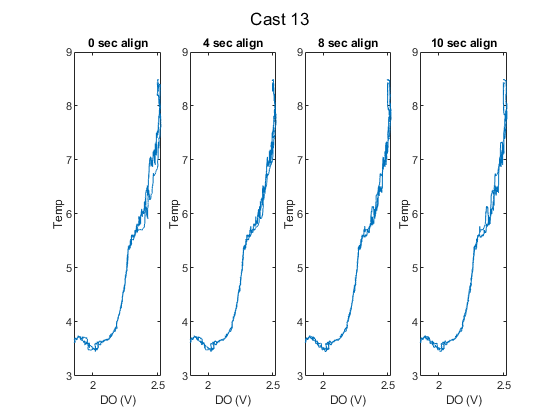

cast13 = align_CTD_KF(cast13,'Cast 13',a1,a2,a3);

% Pick align_sec
a2 = 8;
align_sec = a2; 

% Process in SBE software with this alignment and Leah's processing
% pipeline
% can probably do this with align_CTD_KF code above

% Read in processed casts
% Processed with 8 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2')
cast01u = readSBScnv( 'uat30_001_hyst_abcdefg.cnv' );
cast02u = readSBScnv( 'uat30_002_hyst_abcdefg.cnv' );
cast03u = readSBScnv( 'uat30_003_hyst_abcdefg.cnv' );
cast04u = readSBScnv( 'uat30_004_hyst_abcdefg.cnv' );
cast05u = readSBScnv( 'uat30_005_hyst_abcdefg.cnv' );
cast06u = readSBScnv( 'uat30_006_hyst_abcdefg.cnv' );
cast07u = readSBScnv( 'uat30_007_hyst_abcdefg.cnv' );
cast08u = readSBScnv( 'uat30_008_hyst_abcdefg.cnv' );
cast09u = readSBScnv( 'uat30_009_hyst_abcdefg.cnv' );
cast10u = readSBScnv( 'uat30_010_hyst_abcdefg.cnv' );
cast11u = readSBScnv( 'uat30_011_hyst_abcdefg.cnv' );
cast12u = readSBScnv( 'uat30_012_hyst_abcdefg.cnv' );
cast13u = readSBScnv( 'uat30_013_hyst_abcdefg.cnv' );

cast01d = readSBScnv( 'dat30_001_hyst_abcdefg.cnv' );
cast02d = readSBScnv( 'dat30_002_hyst_abcdefg.cnv' );
cast03d = readSBScnv( 'dat30_003_hyst_abcdefg.cnv' );
cast04d = readSBScnv( 'dat30_004_hyst_abcdefg.cnv' );
cast05d = readSBScnv( 'dat30_005_hyst_abcdefg.cnv' );
cast06d = readSBScnv( 'dat30_006_hyst_abcdefg.cnv' );
cast07d = readSBScnv( 'dat30_007_hyst_abcdefg.cnv' );
cast08d = readSBScnv( 'dat30_008_hyst_abcdefg.cnv' );
cast09d = readSBScnv( 'dat30_009_hyst_abcdefg.cnv' );
cast10d = readSBScnv( 'dat30_010_hyst_abcdefg.cnv' );
cast11d = readSBScnv( 'dat30_011_hyst_abcdefg.cnv' );
cast12d = readSBScnv( 'dat30_012_hyst_abcdefg.cnv' );
cast13d = readSBScnv( 'dat30_013_hyst_abcdefg.cnv' );

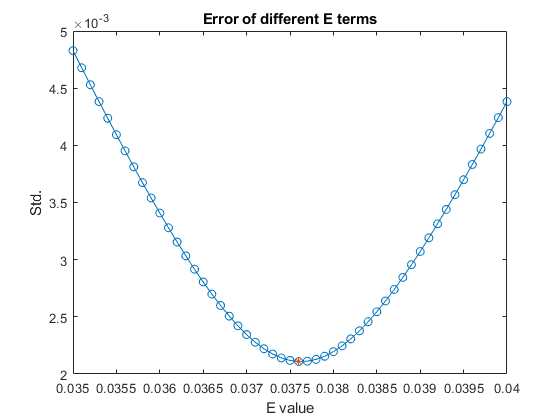

cal.E2 = 0.0376


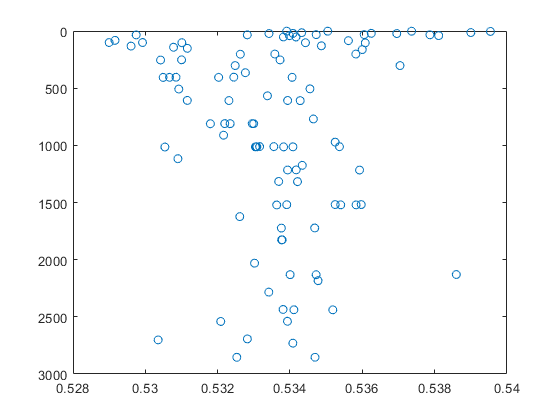

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
[cal] = E2_calculation(btlsum0,cal); % Use dummy bottle summary with outlier removed

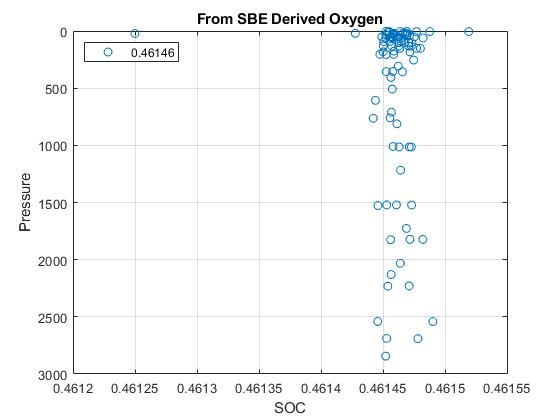

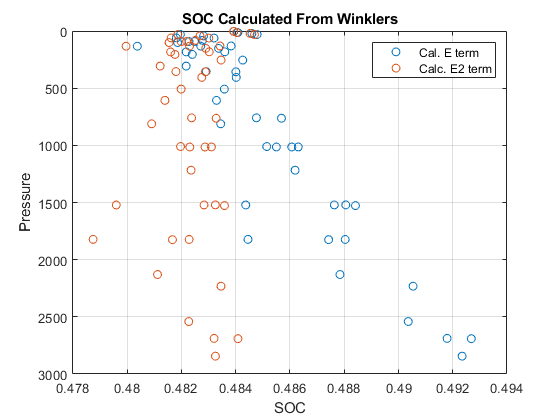

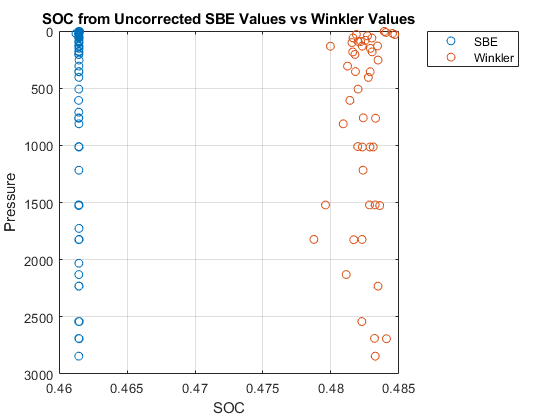

New SOC = 0.48241
EGain = 1.0454+/- 0.0025802


[cal] = Gain_E2_Calculation(btlsum0,cal); % Use dummy bottle summary with any outliers removed

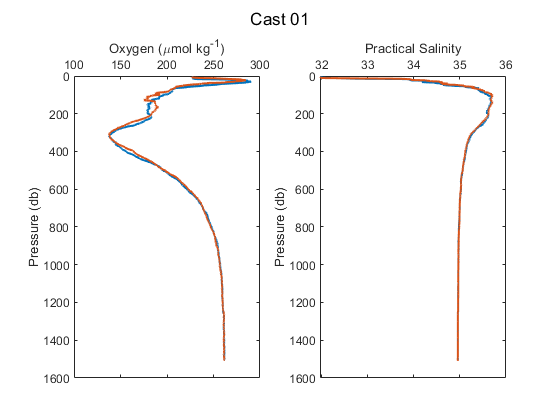

[cast01u, cast01d, btlsum01] = Process_Cast_Gain_E2(cast01u,cast01d,cal,0,1,'Cast 01');

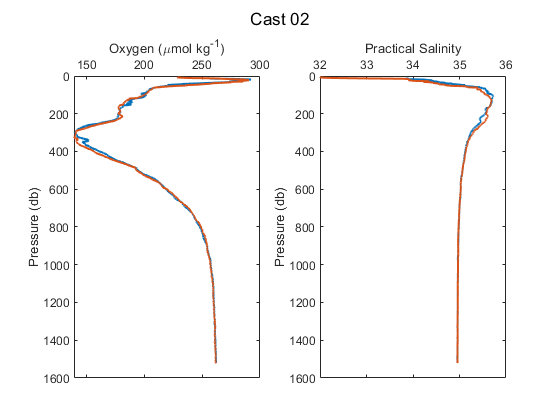

[cast02u, cast02d, btlsum02] = Process_Cast_Gain_E2(cast02u,cast02d,cal,0,1,'Cast 02');

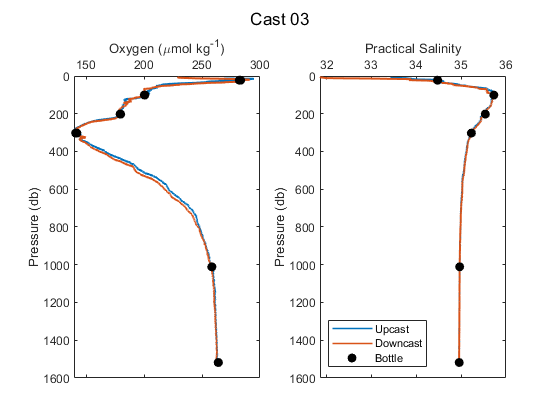

[cast03u, cast03d, btlsum03] = Process_Cast_Gain_E2(cast03u,cast03d,cal,btlsum03,1,'Cast 03');

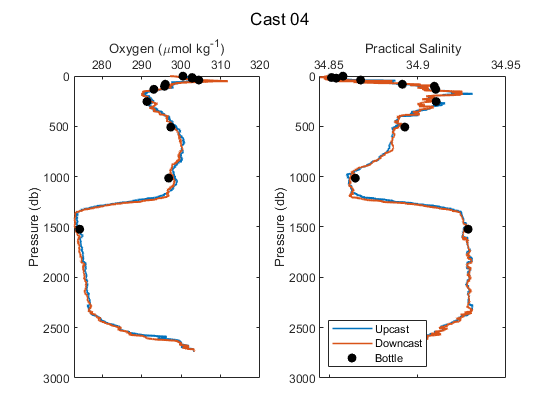

[cast04u, cast04d, btlsum04] = Process_Cast_Gain_E2(cast04u,cast04d,cal,btlsum04,1,'Cast 04');

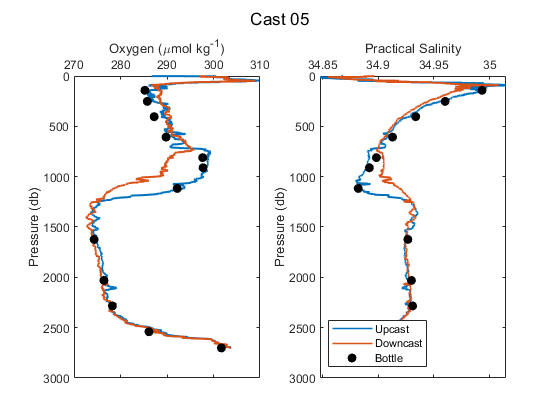

[cast05u, cast05d, btlsum05] = Process_Cast_Gain_E2(cast05u,cast05d,cal,btlsum05,1,'Cast 05');

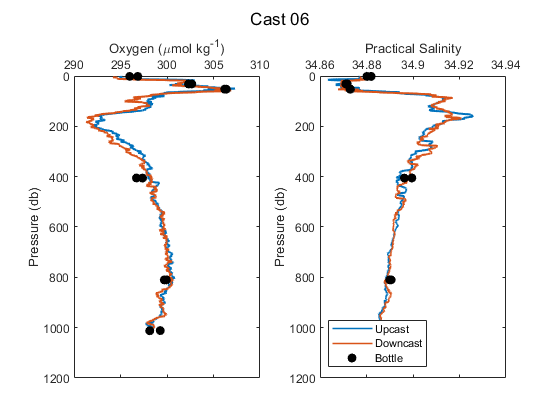

[cast06u, cast06d, btlsum06] = Process_Cast_Gain_E2(cast06u,cast06d,cal,btlsum06,1,'Cast 06');

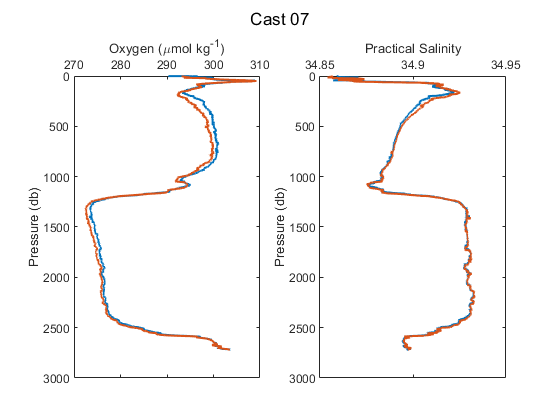

[cast07u, cast07d, btlsum07] = Process_Cast_Gain_E2(cast07u,cast07d,cal,0,1,'Cast 07');

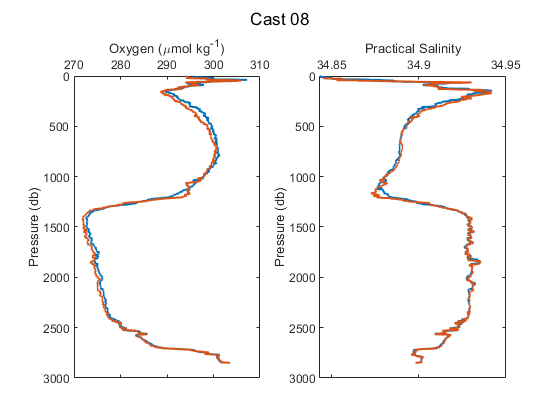

[cast08u, cast08d, btlsum08] = Process_Cast_Gain_E2(cast08u,cast08d,cal,0,1,'Cast 08');

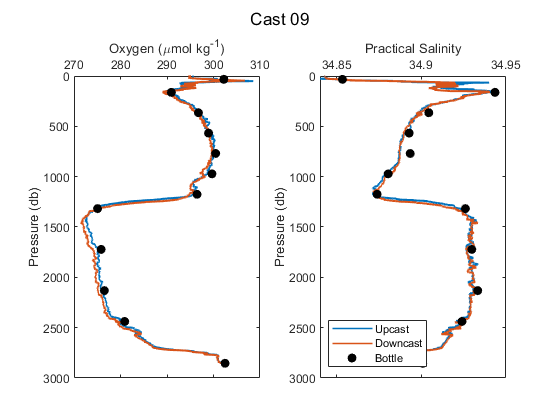

[cast09u, cast09d, btlsum09] = Process_Cast_Gain_E2(cast09u,cast09d,cal,btlsum09,1,'Cast 09');

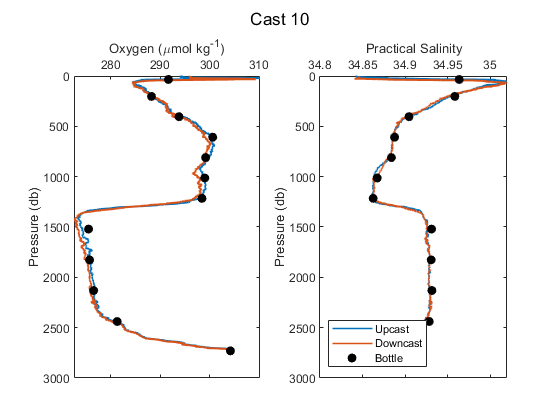

[cast10u, cast10d, btlsum10] = Process_Cast_Gain_E2(cast10u,cast10d,cal,btlsum10,1,'Cast 10');

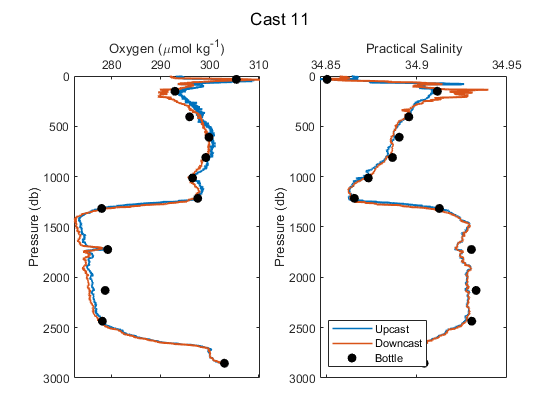

[cast11u, cast11d, btlsum11] = Process_Cast_Gain_E2(cast11u,cast11d,cal,btlsum11,1,'Cast 11');

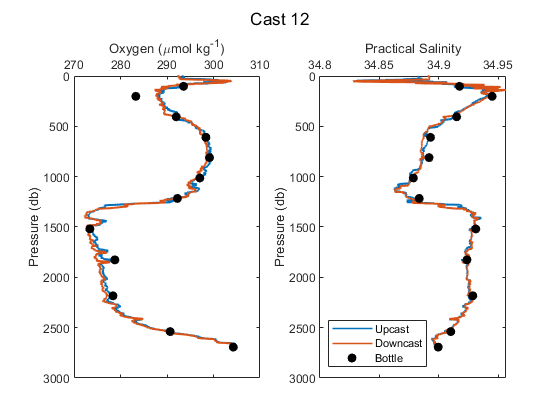

[cast12u, cast12d, btlsum12] = Process_Cast_Gain_E2(cast12u,cast12d,cal,btlsum12,1,'Cast 12');

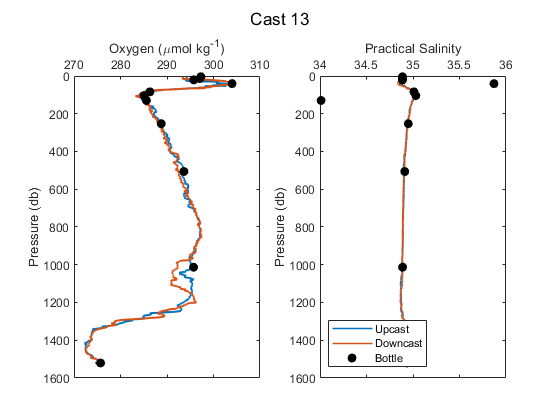

[cast13u, cast13d, btlsum13] = Process_Cast_Gain_E2(cast13u,cast13d,cal,btlsum13,1,'Cast 13');

btlsum_yr2 = [btlsum03; btlsum04; btlsum05; btlsum06; btlsum09; btlsum10; btlsum11;...
    btlsum12; btlsum13];

disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 8


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term (E2) = ' num2str(cal.E2)])

Adjust. E term (E2) = 0.0376


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.51515


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.53365


disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])

E2Gain = 1.0359+/- 0.0040938


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2')
clear btlsum0
dt_Processed = datetime;
save Year2_Processed_KF cast* btl* cal* dt_Processed 
